% Encabezado...
disp('-----------------------------------------------');

-----------------------------------------------


disp('PRACTICA 02. FUNDAMENTOS DE MATLAB');

PRACTICA 02. FUNDAMENTOS DE MATLAB


disp('-----------------------------------------------');

-----------------------------------------------


disp('  Nombre: Fernando Huilca');

  Nombre: Fernando Huilca


disp('  Fecha: 06/01/2024');

  Fecha: 06/01/2024


disp('  Profesor: Andrés Larco');

  Profesor: Andrés Larco


disp('-----------------------------------------------');

-----------------------------------------------



% Aquí comienza el código de la práctica...

## Vectores y Matrices

Una matriz es un objeto rectangular que consta de filas y columnas, mientras que un vector es un tipo especial de matriz que tiene solo una fila o una columna.

- Los elementos de la lista deben estar encerrados entre corchetes. 

-  Los elementos de la lista deben estar separados por espacios o comas.

x = [1 3 0 -1 5]

x =           1.00          3.00             0         -1.00          5.00


disp(x)

          1.00          3.00             0         -1.00          5.00



El comando 'who' muestra el tamaño del vector:

whos

  Name      Size            Bytes  Class     Attributes

  A         1x5                40  double              
  B         1x5                40  double              
  a         1x1                 8  double              
  ans       1x1                 8  double              
  fact      1x1                 8  double              
  i         1x1                 8  double              
  k         1x1                 8  double              
  n         1x1                 8  double              
  r         1x1                 8  double              
  x         1x5                40  double              



a = [1 2 3];
b = [4 5];
c = [a -b];
disp(c)

          1.00          2.00          3.00         -4.00         -5.00



Se pueden usar comas, si se desea:

x = [1,3,0,-1,5]

x =           1.00          3.00             0         -1.00          5.00


disp(x)

          1.00          3.00             0         -1.00          5.00



## Inicialización de vectores: el operador dos puntos

Se puede iniciar un vector con el operador dos puntos (:).

x = 1:10

x =           1.00          2.00          3.00          4.00          5.00          6.00          7.00          8.00          9.00         10.00


x = 1:0.5:4

x =           1.00          1.50          2.00          2.50          3.00          3.50          4.00


x = 10:-1:1

x =          10.00          9.00          8.00          7.00          6.00          5.00          4.00          3.00          2.00          1.00


x = 1:2:6

x =           1.00          3.00          5.00


x = 0:-2:-5

x =              0         -2.00         -4.00


## Funicion Linspace:

La función `linspace` se puede utilizar para inicializar un vector de valores igualmente espaciados. Por ejemplo:

linspace(0, pi/2, 10)

ans =              0          0.17          0.35          0.52          0.70          0.87          1.05          1.22          1.40          1.57


Ejercicio: crea un vector de 10 puntos igualmente espaciados de 0 a π / 2

vector = linspace(0, pi/2, 10);
disp(vector);

             0          0.17          0.35          0.52          0.70          0.87          1.05          1.22          1.40          1.57



## Transposing vectors

Los vectores de fila tienen una fila y varias columnas. 

Para generar los vectores de columna se debe transponer dichos vectores, es decir, debe intercambiar sus filas y columnas. 

Esto se hace con comillas simples o apóstrofo (’)

x = 1:5

x =           1.00          2.00          3.00          4.00          5.00


x'

ans =           1.00
          2.00
          3.00
          4.00
          5.00


Para crear un vector columna directamente: 

 y = [1 4 8 0 -1]'

y =           1.00
          4.00
          8.00
             0
         -1.00


Esto le da un vector de fila de siete números aleatorios

 r = rand (1,7)

r =           0.28          0.05          0.10          0.82          0.69          0.32          0.95


## Matrices

Creas una matriz tal como lo haces con un vector, excepto que se usa un punto y coma para indicar el final de una fila, por ejemplo:

a = [1 2 3; 4 5 6]

a =           1.00          2.00          3.00
          4.00          5.00          6.00


Se puede transponer dicha matriz

a = [1 2 3; 4 5 6]

a =           1.00          2.00          3.00
          4.00          5.00          6.00


a'

ans =           1.00          4.00
          2.00          5.00
          3.00          6.00


Se puede construir una matriz a partir de vectores de columna de la misma longitud.

x = 0:30:180;
table = [x' sin(x*pi/180)']

table =              0             0
         30.00          0.50
         60.00          0.87
         90.00          1.00
        120.00          0.87
        150.00          0.50
        180.00          0.00


Las matrices son el corazón de MATLAB:

a = [1 3 5; 2 4 6; 7 8 10]

x =           1.00          2.00          3.00          4.00          5.00


ans =           1.00
          2.00
          3.00
          4.00
          5.00


y =           1.00
          4.00
          8.00
             0
         -1.00


r =           0.03          0.44          0.38          0.77          0.80          0.19          0.49


a =           1.00          2.00          3.00
          4.00          5.00          6.00


ans =           1.00          4.00
          2.00          5.00
          3.00          6.00


table =              0             0
         30.00          0.50
         60.00          0.87
         90.00          1.00
        120.00          0.87
        150.00          0.50
        180.00          0.00


a =           1.00          3.00          5.00
          2.00          4.00          6.00
          7.00          8.00         10.00


ans =           1.00          2.00          7.00
          3.00          4.00          8.00
          5.00          6.00         10.00


ans =          11.00         13.00         15.00
         12.00         14.00         16.00
         17.00         18.00         20.00


z =              0
             0
             0
             0
             0


y =           1.00
          1.00
          1.00
          1.00
          1.00


A =           1.00          3.00          5.00          7.00          9.00
             0         -2.00          4.00          6.00         -1.00
          1.00          1.00          1.00          1.00          1.00


B =           1.00          2.00          3.00          4.00          5.00          6.00          7.00          8.00          9.00
         -1.00         -2.00         -3.00         -4.00         -5.00         -6.00         -7.00          9.00          2.00
             0             0             0             0             0             0             0             0             0
          3.00          3.00          3.00          3.00          3.00          3.00          3.00          3.00          3.00
          9.00          8.00          7.00          6.00          5.00          4.00          3.00          2.00          1.00


a'
a + 10
z = zeros(5,1)
y = ones (5,1)
A=[1:2:9; 0 -2 4 6 -1; ones(1,5)]
B=[1 2 3 4 5 6 7 8 9; -1 -2 -3 -4 -5 -6 -7 9 2;
zeros(1,9); 3*ones(1,9); 9:-1:1]

## Vertical motion under gravity 

Si se lanza una piedra verticalmente hacia arriba con una rapidez inicial **u = 60m/s**, su desplazamiento vertical s después de un tiempo t ha transcurrido está dado por la fórmula **s = **u*t - g/2*t.^2 , donde g es la aceleración debida a gravedad. Se ha ignorado la resistencia del aire. Nos gustaría calcular el valor de s durante un período de unos **12.3 segundos **a intervalos de **0.1 segundos**, y para trazar el gráfico de distancia-tiempo sobre este período. 

El plan de estructura para este problema es el siguiente: 

    1. Asigne los datos (g, u and t) a las variables de MATLAB. 

    2. Calcule el valor de s según la fórmula. 

    3. Trace la gráfica de s contra t. 

    4. Detener.

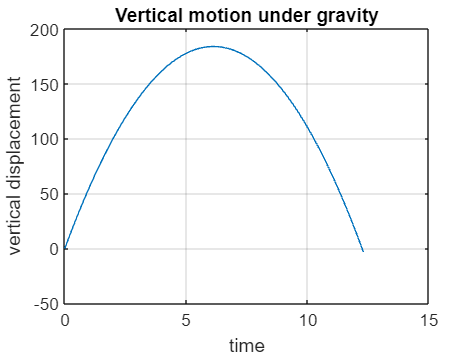

% Vertical motion under gravity
g = 9.8; % acceleration due to gravity
u = 60; % initial velocity (meters/sec)
t = 0 : 0.1 : 12.3; % time in seconds
s = u * t - g / 2 * t .^ 2; % vertical displacement in meters
plot(t, s), title( 'Vertical motion under gravity' ),
xlabel( 'time' ), ylabel( 'vertical displacement' ), grid

disp( [t' s'] ) % display a table

             0             0
          0.10          5.95
          0.20         11.80
          0.30         17.56
          0.40         23.22
          0.50         28.77
          0.60         34.24
          0.70         39.60
          0.80         44.86
          0.90         50.03
          1.00         55.10
          1.10         60.07
          1.20         64.94
          1.30         69.72
          1.40         74.40
          1.50         78.97
          1.60         83.46
          1.70         87.84
          1.80         92.12
          1.90         96.31
          2.00        100.40
          2.10        104.39
          2.20        108.28
          2.30        112.08
          2.40        115.78
          2.50        119.38
          2.60        122.88
          2.70        126.28
          2.80        129.58
          2.90        132.79
          3.00        135.90
          3.10        138.91
          3.20        141.82
          3.30        144.64
          3.40

## Operators, expressions and statements

MATLAB se ha descrito como “un lenguaje basado en expresiones. Interpreta y evalúa expresiones escritas

Las expresiones se construyen a partir de una variedad de cosas, como números, variables y operadores.

Lo que básicamente hace es evaluar expresiones, como:

`u*t - g/2*t.^2 `

y ejecutar (llevar a cabo) declaraciones, como:

`balance = balance + interest`

## Numbers

Los números pueden ser representados en notación científica:

Por ejemplo:

- 1.2345 × 10^9

1.2345e9

ans =  1234500000.00


- 0.000000001

1e-9

ans =           0.00


## Ejercicios:

Ingrese los siguientes números en el símbolo del sistema en notación científica.

1.234 × 10^5, − 8.765 × 10^−4, 10^−15, − 10^12 .

1.234e5

ans =      123400.00


-8.765e-4

ans =          -0.00


10e-15

ans =           0.00


-10e12

ans =  -10000000000000.00


## Data types

Operaciones aritméticas entre dos escalares:

- **Adición: a + b**

- **Sustracción:** **a - b**

- **Multiplicación: a * b**

- **División derecha:** **a / b**

- **División izquierda:** **a \ b, es decir b / a**

- **Potencia:** **a ^ b**

## Precedence of operators

La prioridad de las operaciones aritméticas:

- Paréntesis

- Potencia, de izquierda a derecha

- Multiplicación y división, de izquierda a derecha

- Adición y sustracción, de izquierda a derecha

#### Ejercicios:

- Evaluar las siguientes expresiones de MATLAB antes de comprobar las respuestas en MATLAB:

1 + 2 * 3

ans =           7.00


4 / 2 * 2

ans =           4.00


1+2 / 4

ans =           1.50


1 + 2\4

ans =           3.00


2*2 ^ 3

ans =          16.00


2 * 3 \ 3

ans =           0.50


2 ^ (1 + 2)/3

ans =           2.67


1/2e-1

ans =           5.00


          2. Utilizar MATLAB para evaluar las siguientes expresiones.

1 / (2*3)

ans =           0.17


2 ^ (2 * 3)

ans =          64.00


1.5e-4 + 2.5e-2

ans =           0.03


## The colon operator

El operador de dos puntos tiene una precedencia menor que +, como se muestra a continuación:

1+1:5

ans =           2.00          3.00          4.00          5.00


Operadores aritméticos que operan elemento por elemento en matrices:

- **Multiplicación:** .*

- **División derecha: **./

- **División izquierda:** .\

- **Potencia: **.^

1+[1:5]

ans =           2.00          3.00          4.00          5.00          6.00


El valor 1 se suma a cada elemento del vector 1:5.

## The transpose operator

El operador de transposición tiene la máxima prioridad. Intentar:

1:5'

ans =           1.00          2.00          3.00          4.00          5.00


Primero se transpone el 5 (¡dentro de sí mismo ya que es un escalar!), y luego se transpone un vector fila.formado. Utilice corchetes si desea transponer todo el vector:

[1:5]'

ans =           1.00
          2.00
          3.00
          4.00
          5.00


## Arithmetic operations on arrays

Ingrese las siguientes declaraciones en la línea de comando:

a = [2 4 8];
b = [3 2 2];
a .* b

ans =           6.00          8.00         16.00


a ./ b

ans =           0.67          2.00          4.00


a + b

ans =           5.00          6.00         10.00


a - b

ans =          -1.00          2.00          6.00


3.*a

ans =           6.00         12.00         24.00


a.^2

ans =           4.00         16.00         64.00


la declaración suma(a .* b) encontrará el producto escalar de a y b

sum(a.*b)

ans =          30.00


## Ejercicios:

Utilizar operaciones de matriz MATLAB para hacer lo siguiente:

         1. Suma 1 a cada elemento del vector [2 3 -1].

 1 + [2 3 -1]

ans =           3.00          4.00             0


         2. Multiplica cada elemento del vector [1 4 8] por 3.

3 * [1 4 8]

ans =           3.00         12.00         24.00


         3. Encuentre el producto matricial de los dos vectores [1 2 3] y [0 -1 1].

[1 2 3] .* [0 -1 1]

ans =              0         -2.00          3.00


         4. Eleva al cuadrado cada elemento del vector [2 3 1].

[2 3 1] .^ 2

ans =           4.00          9.00          1.00


## Expressions

Una expresión es una fórmula que consta de variables, números, operadores y nombres de funciones. Una expresión se evalúa cuando la ingresa en el indicador de MATLAB, p. evaluar 2π de la siguiente manera:

2 * pi

ans =           6.28


## Statements 

Las declaraciones de MATLAB suelen tener la forma:

`variable = expresión`

`Por ejemplo:`

% s = u * t - g / 2 * t.^2

Básicamente, cualquier línea que ingrese en la ventana de comandos o en un programa que MATLAB acepte es una declaración, por lo que una declaración podría ser una asignación, un comando o simplemente una expresión, por ejemplo.

x = 29; % asignación
clear % comando
pi/2 % expresión

ans =           1.57


## Vectorization of formulae

Con las operaciones de matriz, puede evaluar fácilmente una fórmula repetidamente para un gran conjunto de datos. Esta es una de las funciones más útiles y potentes de MATLAB, y siempre debe buscar formas de aprovecharla. 

Por ejemplo, el cálculo del interés compuesto. Una cantidad de dinero A invertida durante un período de n años con una tasa de interés anual de r crece hasta una cantidad A(1 +r) n. Supongamos que queremos calcular los saldos finales de inversiones de $750, $1000, $3000, $5000 y $11 999, durante 10 años, con una tasa de interés del 9 por ciento. El siguiente programa (intcomp.m) utiliza operaciones de matriz en un vector de inversiones iniciales para hacer esto

format bank
A = [750 1000 3000 5000 11999];
r = 0.09;
n = 10;
B = A*(1 + r)^n;
disp([A' B'])

        750.00       1775.52
       1000.00       2367.36
       3000.00       7102.09
       5000.00      11836.82
      11999.00      28406.00



## Repeating with `for`

Algunos ejemplos:

for i = 1:5, disp(i), end

          1.00

          2.00

          3.00

          4.00

          5.00



for i = 1:3, disp(i), end

          1.00

          2.00

          3.00



for i = 1:0, disp(i), end

## Raíces cuadradas con el método de Newton

La raíz cuadrada x de cualquier número positivo a se puede encontrar usando solo las operaciones aritméticas de suma, resta y división con el método de Newton. Este es un procedimiento iterativo (repetitivo) que refina una suposición inicial. 

El plan estructural:

         1. Inicializar a

         2. Inicializar x a a/2

         3. Repetir 6 veces (digamos), reemplazar x por (x + a/x)/2,              mostrar x

         4. Detener.

En el programa equivale a lo siguiente: 

a = 2;
x = a/2;
disp(['The approach to sqrt(a) for a = ', num2str(a)])

The approach to sqrt(a) for a = 2


for i = 1:6
 x = (x + a / x) / 2;
 disp( x )
end

          1.50

          1.42

          1.41

          1.41

          1.41

          1.41



disp( 'Matlab''s value: ' )

Matlab's value: 


disp( sqrt(2) )

          1.41



## Factoriales!

Ejecute el siguiente programa para generar una lista de n y n. Que representan el factorial de 10:

n! = 1 * 2* 3 * .... * (n-1)xn

n = 10;
fact = 1;
for k = 1:n
 fact = k * fact;
 disp( [k fact] )
end

          1.00          1.00

          2.00          2.00

          3.00          6.00

          4.00         24.00

          5.00        120.00

          6.00        720.00

          7.00       5040.00

          8.00      40320.00

          9.00     362880.00

         10.00    3628800.00



## Decisiones

La función `rand `de MATLAB genera un número aleatorio en el rango 0-1.

La función rand de MATLAB genera un número aleatorio en el rango 0-1. Ingresar las siguientes dos declaraciones en la línea de comando: 

r = rand

r =           0.45


if r > 0.5 
    disp( 'greater indeed' ), end

Operadores relacionales:

- **Menor que: **<

- **Menor o igual que:** <=

- **Igual: ==**

- **No es igual:** ~=

- **Mayor que:** >

- **Mayor o igual que:** >=